# Error Distribution

## Parameters

n = 1000; % number of test case
d = 16; % dimension of matrix
prob0 = 0.2;
comm_data = zeros(1,n * (n - 1) / 2);
count = 1;


## Commutator

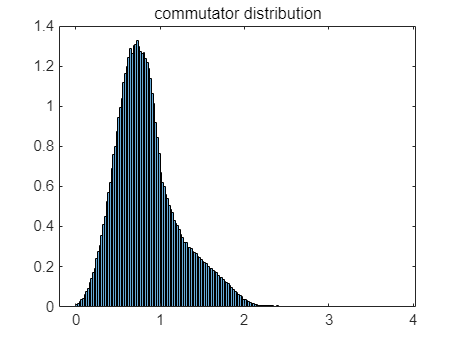

As = cell(1,n);
for j = 1:n
    A = genSparse(d,1,1,prob0);
    As{j} = A{1};
end

for j = 1:n
    for k = j+1:n
        Aj = As{j};
        Ak = As{k};
        commu = Aj*Ak - Ak*Aj;
        comm_data(count) = norm(full(commu),2);
        count = count + 1;
    end
end


histogram(comm_data, 'Normalization', 'pdf');
title('Commutator distribution');

## Trotter Error

n = 10000

n = 10000

% sample range 
t = 0.1;
trot_err_data = zeros(1,n);

for j = 1:n
    s = floor(log(d));
    As = genSparse(d,s,6*s^2,prob0);
    eps = epsA(As,t,1);
    trot_err_data(j) = eps;
end




## Download pdf

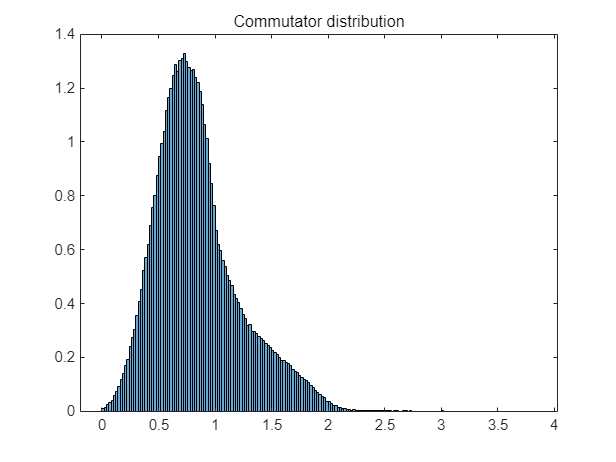

% Save the first histogram as a separate PDF
figure;
histogram(comm_data, 'Normalization', 'pdf');
title('Commutator distribution');
set(gcf, 'PaperPositionMode', 'auto');
saveas(gcf, 'commutator_distribution.pdf');

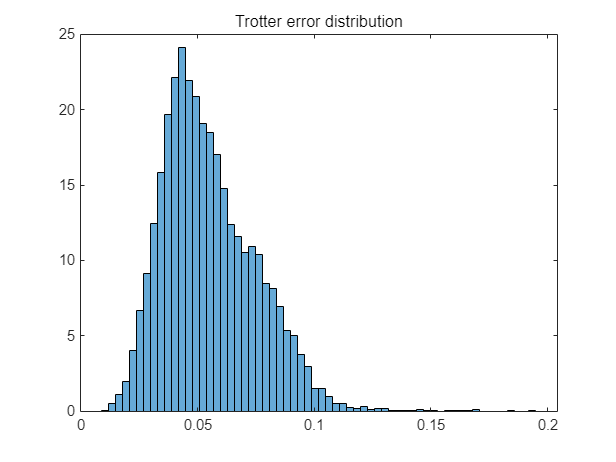


% Save the second histogram as a separate PDF
figure;
histogram(trot_err_data, 'Normalization', 'pdf');
title('Trotter error distribution');
set(gcf, 'PaperPositionMode', 'auto');
saveas(gcf, 'trotter_error_distribution.pdf');